clear 

FileTable = [
% '01_01.mat';        % 1
% '01_02.mat';
%     '02_01.mat';
'03_01.mat';
'04_01.mat';        % 5
'05_01.mat';
% '07_01.mat';
'08_01.mat';
'09_01.mat';
%     '10_01.mat';        % 10
%     '12_01.mat';
% '13_01.mat';
% '14_01.mat';
'15_01.mat';
% '17_01.mat';        % 15
% '18_01.mat';
  '19_01.mat';
%     '20_01.mat';
% '21_01.mat';
% '22_01.mat';        % 20
'23_01.mat';
% '24_01.mat';
% '25_01.mat';
% '26_01.mat';
% '27_01.mat';        % 25
% '28_01.mat';
% '28_02.mat';
% '29_01.mat';
'30_01.mat';
% '32_01.mat';        % 30
% '33_01.mat';
'34_01.mat';
'35_01.mat';
];
Nfile = size(FileTable,1); 
DirName = './W203_5';

Distance.org = nan;
Distance.h = nan;
Hdop.org = nan;
Hdop.h = nan;
 
for iFile = 1:Nfile
    FileName = FileTable(iFile,:);
    [distanceFilter,hdopFiltered] = AnalysisCdf(DirName,FileName);
    
    Distance.org = [Distance.org;distanceFilter.org];
    Distance.h = [Distance.h;distanceFilter.h];
    
    Hdop.org = [Hdop.org;hdopFiltered.org];
    Hdop.h = [Hdop.h;hdopFiltered.h];
end

ans = 87

ans = 118

ans = 429

ans = 258

ans = 276

ans = 139

ans = 569

ans = 279

ans = 167

ans = 117

ans = 463

ans = 247

ans = 222

ans = 123

ans = 487

ans = 277

ans = 234

ans = 132

ans = 549

ans = 270

ans = 133

ans = 111

ans = 439

ans = 274

ans = 148

ans = 124

ans = 378

ans = 279

ans = 78

ans = 41

ans = 470

ans = 297

ans = 72

ans = 91

ans = 266

ans = 254

ans = 62

ans = 93

ans = 374

ans = 239

ans = 79

ans = 14

ans = 275

ans = 245

Distance.org = Distance.org(2:end);
Distance.h = Distance.h(2:end);

Hdop.org = Hdop.org(2:end);
Hdop.h = Hdop.h(2:end);

ts = 'sat=5,50%';

length(Distance.org)

ans = 1558

length(Distance.h)

ans = 1103

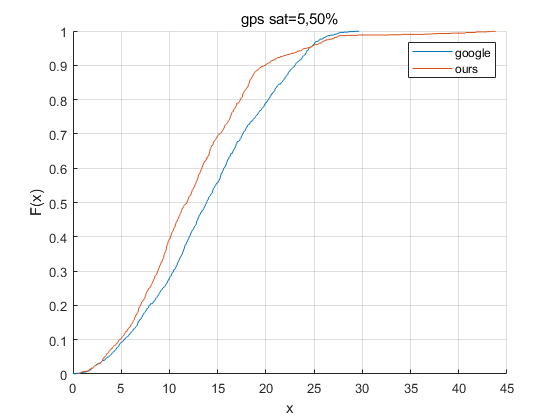

figure
hold on
cdfplot(Distance.org)
cdfplot(Distance.h)
legend('google','ours')
title(['gps ' ts])
hold off


length(Hdop.org)

ans = 4699

length(Hdop.h)

ans = 2919

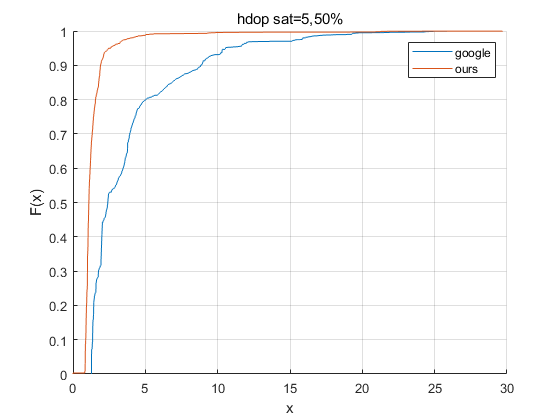

figure
hold on
cdfplot(Hdop.org)
cdfplot(Hdop.h)
legend('google','ours')
title(['hdop ' ts])
hold off